# Finding nth roots of 1 in MATLAB using live scripts

Take for example the cubic equation:


$$\left( x-1\right) \left( x^2 + x + 1 \right) = 0$$


The first cube root is easy, being $x = \pm \sqrt(1) = \pm 1$, the higher-order roots require more work.

Quadratic formula for second and third cube roots:


$$x = \frac{-b \pm \sqrt{b^2 - 4ac}}{2a}$$
 

a = 1; b = 1; c = 1;
roots = [];
roots(1) = 1;
roots(2) = (-b + sqrt(b^2 - 4*a*c))/(2*a);
roots(3) = (-b - sqrt(b^2 - 4*a*c))/(2*a);
disp(roots')

   1.0000 + 0.0000i
  -0.5000 - 0.8660i
  -0.5000 + 0.8660i



Ahhhhh complex roots, let's plot them on the complex plane then

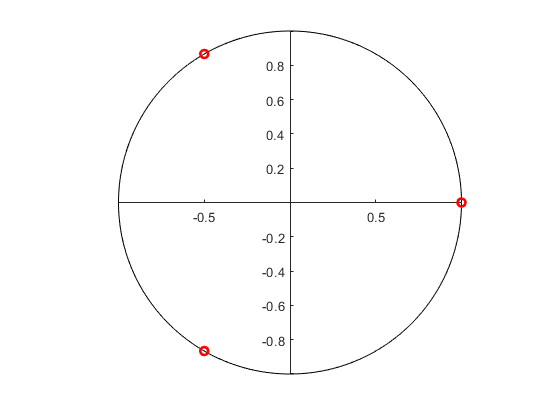

range = 0:0.01:2*pi; % A circle in increments of 0.01
plot(cos(range), sin(range), 'k')
axis square; box off;
ax = gca; % gca is the current axes, assigning to ax means
% % we can access the attributes of the axes
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
hold on
plot(real(roots), imag(roots), 'ro', 'LineWidth',2)

## Finding higher order roots

4th roots we could use a quartic formula, but this unwieldy and not very elegant

Let's use de Moivre's theorem! Which links complex numbers and trigonometry.

Theorem states that for any real x and any integer n,


$$\left( \mathrm{cos}x + i  \mathrm{sin}x \right) ^n = \mathrm{cos} (nx) + i \mathrm{sin} (nx)$$


We also know that for any integer k,


$$1 = \mathrm{cos} (2k \pi) + i \mathrm{sin} (2k \pi)$$


Combined gives


$$1^{1/n} = \left( \mathrm{cos} (2k \pi) + i \mathrm{sin} (2k \pi) \right)^{1/n} = \mathrm{cos} \left( \frac{2k \pi}{n} \right) + i\mathrm{sin} \left( \frac{2k \pi}{n} \right)$$


#### Calculating the nth roots of 1

Using the last equation we can find the nth roots of 1. For any value of n, we can use the formula with values of $k=0 \ ...\  n-1$

n = 11;
roots = zeros(1,n);
for k=0:n-1
    roots(k+1) = cos(2*k*pi/n) + 1i*sin(2*k*pi/n);
end
disp(roots');

   1.0000 + 0.0000i
   0.8413 - 0.5406i
   0.4154 - 0.9096i
  -0.1423 - 0.9898i
  -0.6549 - 0.7557i
  -0.9595 - 0.2817i
  -0.9595 + 0.2817i
  -0.6549 + 0.7557i
  -0.1423 + 0.9898i
   0.4154 + 0.9096i
   0.8413 + 0.5406i



Now again plotting in the complex plane, we can see the roots are equally spaced around the circle at intervals of $\frac{2 \pi}{n}$

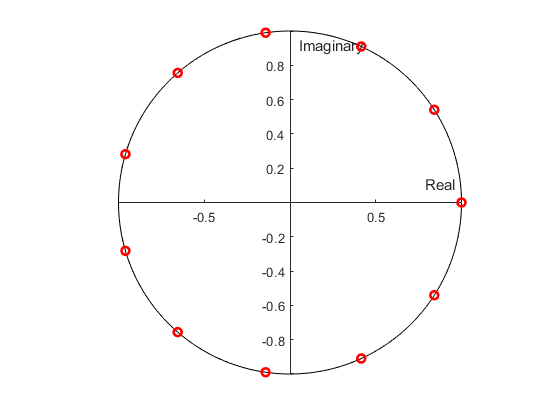

cla;
plot(cos(range), sin(range),'k')
hold on
plot(real(roots),imag(roots), 'ro', 'LineWidth',2)
xlabel('Real')
ylabel('Imaginary')